# Slosh 3D, rotation about z axis 

Different parametrization of the pendulum

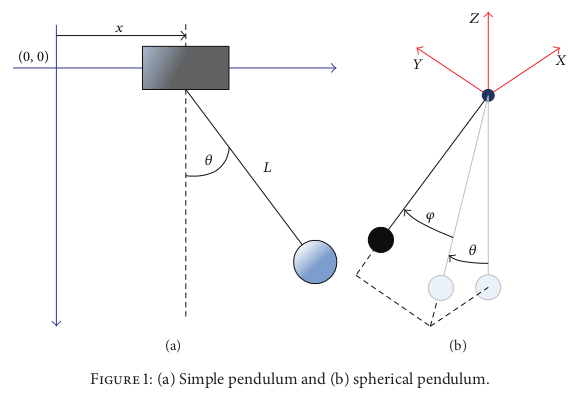

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the z axis of the container.

clc 
clear all

syms theta_p(t) phi_c(t) theta(t) psi(t) phi(t)
syms t 
syms dx(t) dy(t) dz(t) h l m g M b J cs
syms x(t) y(t) z(t) xc(t) yc(t) zc(t)
sympref('AbbreviateOutput',false);

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\psi$ =  rotation of the pendulum about its longitudinal axis z

$\phi_c$ = rotation of the container about its longitudinal axis

$\theta_p$ = rotation of the pendulum about its longitudinal axis

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container with origin coincident with the pivot of the pendulum

- Frame of the liquid object with origin coincident with the pivot of the pendulum

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to liquid

Derive the homogeneous transformation matrix from the world to the liquid reference frame.

The transformation from inertial frame to container frame will be skipped because the dependance of the rotation of the container is mapped into the rotation of the liquid through a friction interaction.

Define rotation matrix (rotation of around the z-axis)

R_z_theta_p = [cos(theta_p), -sin(theta_p), 0;
               sin(theta_p), cos(theta_p), 0;
               0,         0,        1];
R_z_theta_p = formula(R_z_theta_p);

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wl = [R_z_theta_p, p; 0 0 0 1];
T_wl = formula(T_wl);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to liquid:');

Homogeneous Transformation Matrix from world to liquid:


disp(T_wl);

$$\left(\begin{array}{cccc} \cos\left(\theta_{p}\left(t\right)\right) & -\sin\left(\theta_{p}\left(t\right)\right) & 0 & x\left(t\right)\\ \sin\left(\theta_{p}\left(t\right)\right) & \cos\left(\theta_{p}\left(t\right)\right) & 0 & y\left(t\right)\\ 0 & 0 & 1 & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Liquid to pivot

Derive the homogeneous transformation matrix from the liquid refernce frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(-theta),  0, sin(-theta); 
             0,           1,           0; 
             -sin(-theta),  0,  cos(-theta)];
R_y_theta = formula(R_y_theta)

$$R\_y\_theta = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$


% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi)

$$R\_x\_phi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_combined = R_y_theta * R_x_phi 

$$R\_combined = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [0; 0; 0];

Create homogeneous transformation matrix

T_lp = [R_combined, p; 0 0 0 1];
T_lp = formula(T_lp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from liquid to pivot:');

Homogeneous Transformation Matrix from liquid to pivot:


disp(T_lp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wl*T_lp*T_pm

$$T\_wm = \left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)-\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & x\left(t\right)-l\,\left(\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right) & -\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right) & y\left(t\right)+l\,\left(\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\right)\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & z\left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)-l\,\left(\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l\,\left(\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)$$

## Derivation of the container coordinates

To be pedantic, the transformation between the world and the container reference frame is as follows

### World to container

Derive the homogeneous transformation matrix from the world to the container reference frame.

Define rotation matrix (rotation of around the z-axis)

R_z_phi_c = [cos(phi_c), -sin(phi_c), 0;
             sin(phi_c),  cos(phi_c), 0;
             0,           0,          1];
R_z_phi_c = formula(R_z_phi_c);

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wc = [R_z_phi_c, p; 0 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to container:');

Homogeneous Transformation Matrix from world to container:


disp(T_wc);

$$\left(\begin{array}{cccc} \cos\left(\varphi_{c}\left(t\right)\right) & -\sin\left(\varphi_{c}\left(t\right)\right) & 0 & x\left(t\right)\\ \sin\left(\varphi_{c}\left(t\right)\right) & \cos\left(\varphi_{c}\left(t\right)\right) & 0 & y\left(t\right)\\ 0 & 0 & 1 & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);
simplify(xm_dot)

$$ans = \frac{\partial }{\partial t}x\left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)$$

simplify(ym_dot)

$$ans = \frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

simplify(zm_dot)

$$ans = \frac{\partial }{\partial t}z\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)$$



wp = diff(theta_p, t);
wp_dot = diff(theta_p, t, t);

wc = diff(phi_c, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\left(\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)+\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)-\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\right)}^{2}}{2}$$

% Tmx = simplify(Tmx);
%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\left(\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\right)}^{2}}{2}$$

% Tmy = simplify(Tmy)
%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

% Tmz = simplify(Tmz)
%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;
simplify(T)

### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);


D = b/2 *(theta_dot^2 + phi_dot^2);
D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{p}\left(t\right)\right)}^{2}-2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{p}\left(t\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,{\cos\left(\phi \left(t\right)\right)}^2\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)-l^2\,m\,{\cos\left(\phi \left(t\right)\right)}^2\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta _{p}\left(t\right)\right)}^2-2\,l^2\,m\,{\cos\left(\phi \left(t\right)\right)}^2\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \theta _{p}\left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+l\,m\,\cos\left(\phi \left(t\right)\right)\,\cos\left(\theta \left(t\rig

eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
disp(eqn1);

$$\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{b\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{p}\left(t\right)\right)}^{2}-2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{p}\left(t\right)}{l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}}$$

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

$$b\,\frac{\partial }{\partial t}\varphi \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+l^{2}\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{p}\left(t\right)+\frac{l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sin\left(\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{p}\left(t\right)\right)}^{2}+2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,m\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l\,m\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

b\,\frac{\partial }{\partial t} \phi \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+l^2\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \theta _{p}\left(t\right)+\frac{l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta \left(t\right)\right)}^2}{2}+l\,m\,\cos\left(\phi \left(t\right)\right)\,\cos\left(\theta _{p}\left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta _{p}\left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)-l^2\,m\,\cos\left(\phi \left(t\right)\right)\,{\cos\left(\theta \left(t\right)\right)}^2\,\sin\left(\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial

eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
disp(eqn2);

$$\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)=-\frac{b\,\frac{\partial }{\partial t}\varphi \left(t\right)+l^{2}\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{p}\left(t\right)+\frac{l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sin\left(\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{p}\left(t\right)\right)}^{2}+2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{p}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,m\,\cos\left(\theta_{p}\left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l\,m\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\theta_{p}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{l^{2}\,m}$$

% Equation of motion linking the angular velocity of the container and the
% angular velocity of the liquid
J*wp_dot == b*(wc - wp)

$$ans(t) = J\,\frac{\partial^{2}}{\partial t^{2}}\theta_{p}\left(t\right)=b\,\left(\frac{\partial }{\partial t}\varphi_{c}\left(t\right)-\frac{\partial }{\partial t}\theta_{p}\left(t\right)\right)$$


$$J\,\frac{\partial^2 }{\partial t^2 }\mathrm{\ }\theta_p \left(t\right)=b\,{\left(\frac{\partial }{\partial t}\mathrm{\ }\phi_c \left(t\right)-\frac{\partial }{\partial t}\mathrm{\ }\theta_p \left(t\right)\right)}$$



$$\Longrightarrow J{\dot{\omega} }_p \left(t\right)=b\,{\left(\omega_c \left(t\right)-\mathrm{\ }\omega_p \left(t\right)\right)}$$
